# Week3 - Communications Channel with BPSK

The code below implements the BPSK modulation scheme and models a general communications channel in the electrical domain. 

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using BPSK

- A pulse shaper which creates an electrical signal using the generated symbols

### Modulation

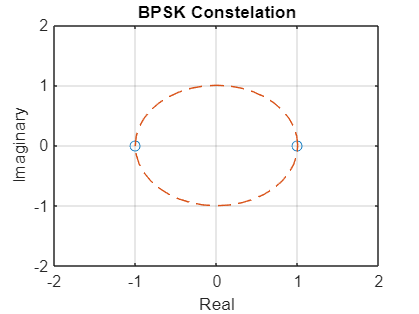

clear all; clearvars;

% Modulation parameters
M = 2; % Modulation order
k = log2(M); % Bits per symbol

% Visualising constellation
alphabet = 0:M-1;
symbols = pskmod(alphabet, M);
plot(real(symbols), imag(symbols), "o");
title("BPSK Constelation");
xlabel("Real");
ylabel("Imaginary");
grid on;
hold on;
phase = [0:pi/20:2*pi];
circleX = cos(phase); circleY = sin(phase);
plot(circleX, circleY, "--");
xlim([-2,2]); ylim([-2,2])
hold off

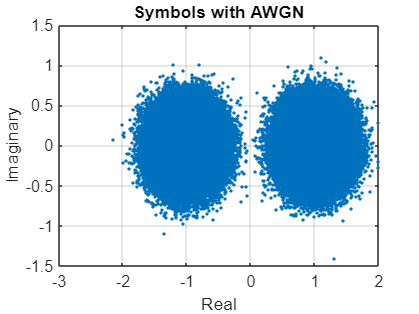


% Generating random bit sequence(s)
NSymb = 500000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
NSequences = 20; % No. of bit sequences

sourceBits = randi([0 1], NSymb*k, NSequences); % Matrix of source bits
sourceSymbols = pskmod(sourceBits, M); % Maps source bit vector to symbol vector

% pskmod mappiung: 0 -> 1+0i and 1 -> -1+0i

% Adding AWGN to the symbols
SNRb_dB = [0:NSequences-1]'; % SNR per bit in dB
powerPerSymb = mean(real(symbols).^2,"all");

for i=1:NSequences
    SNRb_Lin(i,1) = 10^(SNRb_dB(i,1)/10); % linear SNR per symbol
    AWGN_StdDev(i,1) = sqrt(powerPerSymb/SNRb_Lin(i,1)); % AWGN Standard deviation
    sourceSymbols_AWGN(:,i) = sourceSymbols(:,i) + (1/sqrt(2))*AWGN_StdDev(i,1)*randn(size(sourceSymbols, 1),1) + (1i/sqrt(2))*AWGN_StdDev(i,1)*randn(size(sourceSymbols, 1),1); % Noisy symbols
end

% Visualising noisy symbols at SNR = 10 dB
plot(real(sourceSymbols_AWGN(:,11)), imag(sourceSymbols_AWGN(:,11)), ".");
title("Symbols with AWGN")
xlabel("Real")
ylabel("Imaginary")
grid on

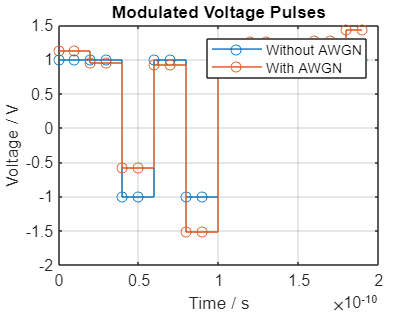


voltageWave = repelem(real(sourceSymbols), SpS, 1); % Matrix of source bits with oversampling according to SpS
voltageWave_AWGN = repelem(real(sourceSymbols_AWGN), SpS, 1); % Matrix of source bits with oversampling according to SpS

T = 1/(SpS*Rs); % Sampling period in sec
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

% Visualising voltage waveform
stairs(t(1:20), voltageWave(1:20,11), "o-");
title("Modulated Voltage Pulses")
xlabel("Time / s")
ylabel("Voltage / V")
grid on
hold on
stairs(t(1:20), voltageWave_AWGN(1:20,11), "o-");
hold off
legend("Without AWGN", "With AWGN")

### Pulse Shaping

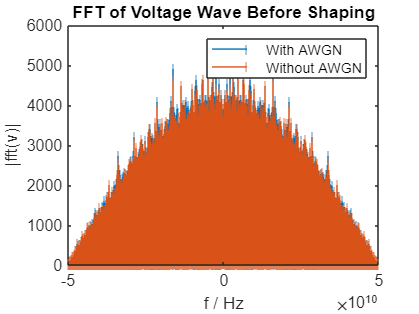

% Frequency spectrum of voltage waveform before filtering
fft_v_AWGN = fftshift(fft(voltageWave_AWGN(:,11)));
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);
stem(freqArr, abs(fft_v_AWGN), "|");
title("FFT of Voltage Wave Before Shaping");
xlabel("f / Hz");
ylabel("|fft(v)|");
hold on
fft_v = fftshift(fft(voltageWave(:,11)));
stem(freqArr, abs(fft_v), "|");
legend("With AWGN", "Without AWGN")
hold off

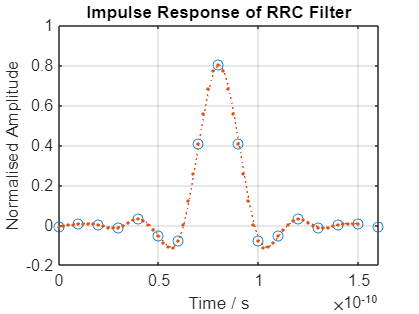


% Visualisation of RRC filter
filterSpan = 8; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
filterResponse_t_interp = [0:0.25:filterSpan*SpS - 1]*T;
filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");
title('Impulse Response of RRC Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

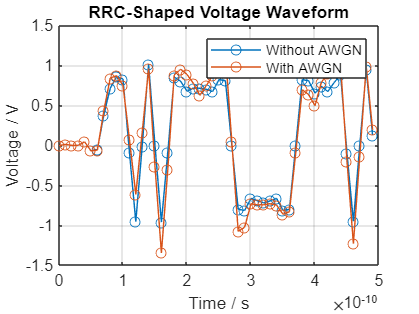


% The generated rectangular voltage pulses are shaped using the RRC filter
shapedV = upfirdn(real(sourceSymbols), filterResponse, SpS, 1);
shapedV_AWGN = upfirdn(real(sourceSymbols_AWGN), filterResponse, SpS, 1);

% Visualising pulse-shaped voltages
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
shapedV_t = [0:1:samples-1]*T; shapedV_t_interp = [0:0.25:samples-1]*T;
shapedV_interp = interp1(shapedV_t, shapedV(:,11), shapedV_t_interp, "spline");
shapedV_AWGN_interp = interp1(shapedV_t, shapedV_AWGN(:,11), shapedV_t_interp, "spline");
% plot(shapedV_t(1:50), shapedV(1:50,11), "o", shapedV_t_interp(1:200), shapedV_interp(1:200), ":.");

plot(shapedV_t(1:50), shapedV(1:50,11), "-o");
hold on
plot(shapedV_t(1:50), shapedV_AWGN(1:50,11), "-o");
title("RRC-Shaped Voltage Waveform")
ylabel("Voltage / V")
xlabel('Time / s');
legend("Without AWGN", "With AWGN")
grid on
hold off

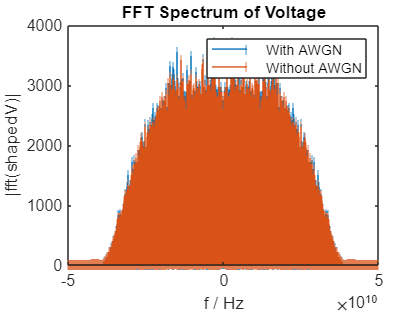


% Frequency spectrum of voltage waveform after filtering
fft_shapedV_AWGN = fftshift(fft(shapedV_AWGN(:,11)));
freqArr = [-samples/2:samples/2 - 1]/(T*samples);
stem(freqArr, abs(fft_shapedV_AWGN), "|");
hold on
fft_shapedV = fftshift(fft(shapedV(:,11)));
stem(freqArr, abs(fft_shapedV), "|");
title("FFT Spectrum of Voltage");
xlabel("f / Hz");
ylabel("|fft(shapedV)|");
legend("With AWGN", "Without AWGN")
hold off


bandwidth = 0.5*(1+rollOff)/T

bandwidth = 7.5000e+10

### Up-Conversion

% % Upconverted BPSK signal suitable for transmission
% 
% % Carrier wave
% c = 299792458; % Speed of light in air in m/s
% lambda = 1300e-9; % Wavelength of light in m
% fc = c/lambda % carrier frequency in Hz
% carrier = cos(2*pi*fc*shapedV_t)';
% 
% % Visualising carrier wave
% carrier_t = [0:0.25:4]/fc; carrier_t_interp = [0:0.125:4]/fc;
% plot(carrier_t, cos(2*pi*fc*carrier_t), "bo-", shapedV_t, carrier, "ro");
% title("Carrier")
% ylabel("Voltage / V")
% xlabel('Time / s');
% grid on
% 
% txOut = carrier.*shapedV;
% 
% % Frequency spectrum of voltage waveform after upconversion
% fft_txOut = fftshift(fft(txOut(:,1)));
% freqArr = [-samples/2:samples/2 - 1]*(fc+1/T)/samples;
% stem(freqArr, abs(fft_txOut), "|");
% title("FFT Spectrum of Voltage");
% xlabel("f / Hz");
% ylabel("|fft(shapedV)|");

## Channel

### Adding AWGN Noise

channelOut = shapedV;
channelOut_AWGN = shapedV_AWGN;

## Receiver

### Matched Filtering

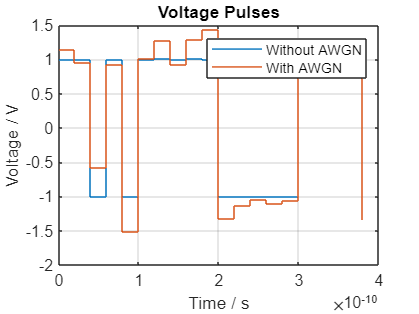

% Apply a matched filter to the recieved signal
% Without AWGN
filteredVoltage = upfirdn(channelOut, filterResponse, 1, SpS); % Filtering -> Downsampling
filteredVoltage = filteredVoltage(filterSpan + 1:end - filterSpan,:); % Removing additional samples from the tails

% With AWGN
filteredVoltage_AWGN = upfirdn(channelOut_AWGN, filterResponse, 1, SpS); % Filtering -> Downsampling
filteredVoltage_AWGN = filteredVoltage_AWGN(filterSpan + 1:end - filterSpan,:); % Removing additional samples from the tails

% Visualising recieved symbols
stairs([0:19]/Rs, filteredVoltage(1:20,11));
hold on
stairs([0:19]/Rs, filteredVoltage_AWGN(1:20,11));
title("Voltage Pulses")
xlabel("Time / s")
ylabel("Voltage / V")
legend("Without AWGN", "With AWGN")
grid on
hold off

### Decision

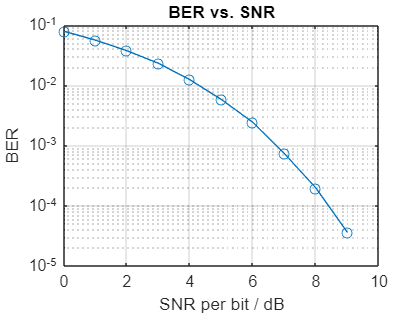

ans =      0     0     0     0     0     0


% Decoding the received symbols using ML detection
decodedBits = filteredVoltage < 0;
decodedBits_AWGN = filteredVoltage_AWGN < 0;

for i=1:NSequences
    [numErrors(i), BER(i)] = biterr(sourceBits(:,i), decodedBits_AWGN(:,i));
end

semilogy(SNRb_dB, BER, 'o-')
title("BER vs. SNR")
ylabel("BER")
xlabel("SNR per bit / dB")
grid on